# Controlled Passive Dynamic Walker Simulation

clear;clc;

pdw.l1 = 2; pdw.l2 = 2;
pdw.m1 = 0.5; pdw.m2 = 0.5; pdw.mh = 0.5;

pdw.gamma = 0;
pdw.fps = 10; % A constant fps will not help with proper simulation
deltat = 2;
L = 10;
x = 1.5; 
y = (L-x)*tan(pdw.gamma);

% Here q = [th1 th2 th1d th2d];
% Requires manual tuning to make the PDW walk on the ramp. Needs some intuition
q0 = [0;0.5;-5;0];

## Integrate

vdes = [-4.5 -4 -3.5 -3 -2.5 -2 -1.5 -1 -0.5];
n = length(vdes);
% n = 7; % Number of steps
tstart = 0;
tsim = [];
qsim = [];

foot_anchor_hook = [x;y;1];
foot_anchor = [];
v_apex = [];

for k = 1:n
    q0 = setLegAngle(q0,vdes(k));
    [t,q,q0next,foot_anchor_temp] = one_step(tstart,deltat,q0,pdw,foot_anchor_hook);    
    tsim = [tsim; t(1:end-1,:)];
    qsim = [qsim; q(1:end-1,:)];    
    foot_anchor = [foot_anchor foot_anchor_temp(:,1:end-1)];  
    foot_anchor_hook = foot_anchor_temp(:,end);
    q0 = q0next;  
    v_apex = [v_apex; q0(3)];
    tstart = t(end);
end

## Animate

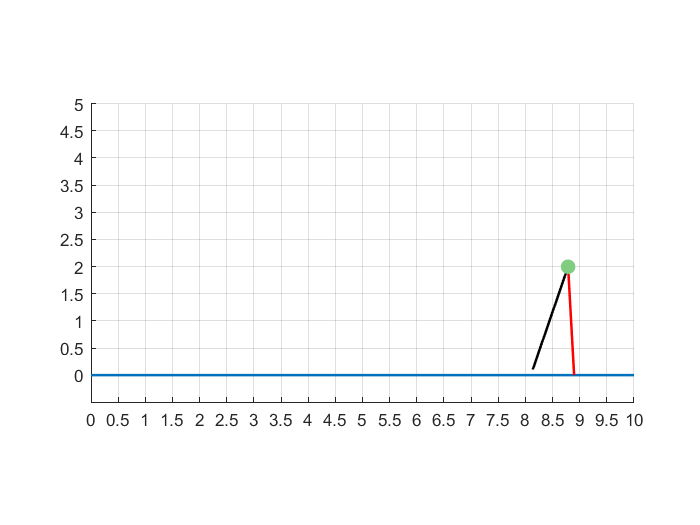

figure(1);
for k=1:length(tsim)
    % [ke,pe,te] = getEnergy(qsim(k,:),pdw,foot_anchor(1:2,k));
    th1 = qsim(k,1); th2 = qsim(k,2);
    Ggh = [foot_anchor(1,k) - pdw.l1*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)); ...
        foot_anchor(2,k) + pdw.l1*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1))];
    GgC2 = [foot_anchor(1,k) - pdw.l1*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)) + pdw.l2*(cos(th2)*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)) + sin(th2)*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1))); ... 
        foot_anchor(2,k) + pdw.l1*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1)) - pdw.l2*(cos(th2)*(cos(pdw.gamma)*cos(th1) + sin(pdw.gamma)*sin(th1)) - sin(th2)*(cos(pdw.gamma)*sin(th1) - cos(th1)*sin(pdw.gamma)))];
    
    if foot_anchor(3,k) > 0
        leg1_color = 'black';
        leg2_color = 'red';
    else
        leg1_color = 'red';
        leg2_color = 'black';
    end
    
    grid on;
    hold on;
    line([0 L],[L*tan(pdw.gamma) 0],'LineWidth',1.5); % Ramp
    h1 = line([foot_anchor(1,k) Ggh(1)],[foot_anchor(2,k) Ggh(2)],'LineWidth',1.5,'Color',leg1_color); % Stance Leg
    h2 = line([Ggh(1) GgC2(1)],[Ggh(2) GgC2(2)],'LineWidth',1.5,'Color',leg2_color); % Swing Leg
    h3 = plot(Ggh(1),Ggh(2),'.','MarkerSize',30,'Color',[0.5 0.8 0.5]); % Hip
    % h4 = text(1,4, ['KE: ' num2str(ke) ' | PE:' num2str(pe) ' | TE:' num2str(te)]);
    axis([0 L -0.5 L/2]);
    xticks(0:0.5:L);
    yticks(0:0.5:L);
    daspect([1 1 1]);
    drawnow;
    
    % pause(0.5);
    if k ~= length(tsim)
        delete(h1);
        delete(h2);
        delete(h3);
        % delete(h4);
    end    
end

## Plot Angles and Angular Velocity

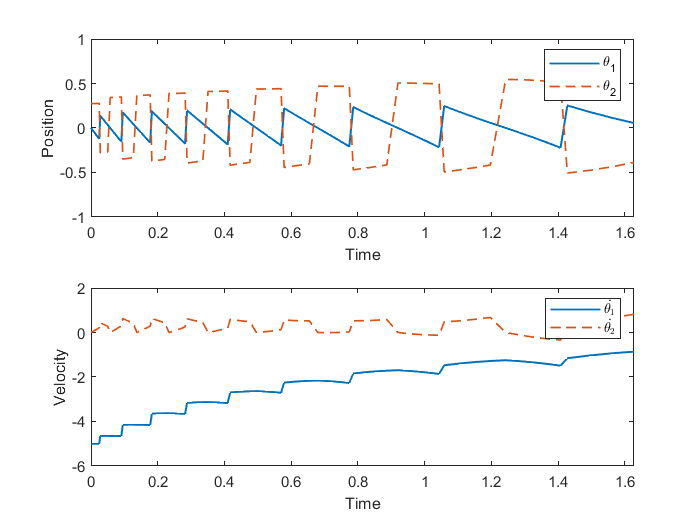

figure(2);
subplot(2,1,1);
plot(tsim,qsim(:,1),'LineWidth',1);
hold on;
plot(tsim,qsim(:,2),'--','LineWidth',1);
ylabel('Position');
xlabel('Time');
axis([0 tsim(end) -1 1]);
legend('\theta_1','\theta_2');
subplot(2,1,2);
plot(tsim,qsim(:,3),'LineWidth',1);
hold on;
plot(tsim,qsim(:,4),'--','LineWidth',1);
ylabel('Velocity');
xlabel('Time');
axis([0 tsim(end) -6 2]);
legend({'$\dot{\theta_1}$', '$\dot{\theta_2}$'}, 'Interpreter', 'latex');

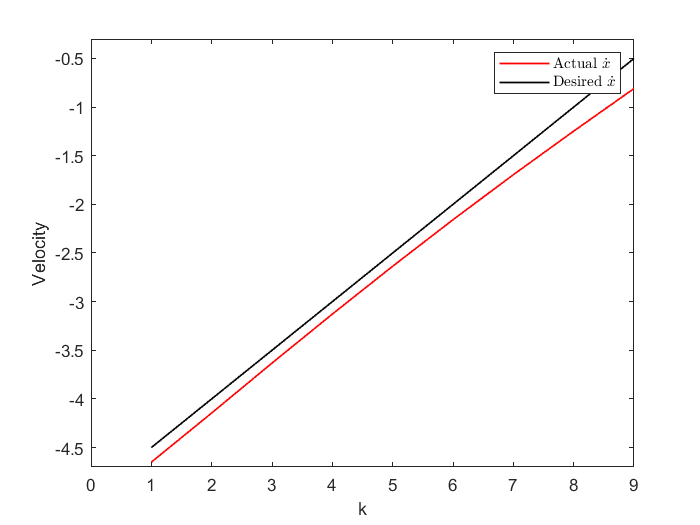

figure(3);
plot(v_apex,'LineWidth',1,'Color','red');
hold on;
plot(vdes,'LineWidth',1,'Color','black');
ylabel('Velocity');
xlabel('k');
axis([0 length(v_apex) min(vdes)-0.2 max(vdes)+0.2])
legend({'Actual $\dot{x}$', 'Desired $\dot{x}$'}, 'Interpreter', 'latex');

## Query Lookup Table for Velocity Control

function qnext = setLegAngle(q,target)
    b = [0.3471 -0.2985 0.3479];
    q(2) = b*[1;q(3);target]; q(4) = 0;
    qnext = q;
end